# Transient Stress in a Fiber Suspension

Chapter 7 develops the following model for extra stress in a fiber suspension:


$$\mathbf{\tau} = 2 \eta_I \left[ \mathbf{D} + N_p \, \mathbb{A}: \mathbf{D}  \right]$$


Here $\eta_I$ is an isotropic viscosity and $N_p$, called the particle number, characterizes the orientation-dependent contributions of the fibers to the stress.  

The function `tauFiber` implements this equation, and can be used to calculate stresses in a suspension subjected to a known rate of deformation and vorticity.  The fiber orientation must be solved first, and a closure approximation used to calculate the fourth-order tensor $\mathbb{A}$ from the second-order tensor $\mathbf{A}$.  

Here we show the calculations used to produce Fig. 6.4, which gives the transient stress in simple shear flow, starting from an isotropic initial condition.  For orientation we use the Folgar-Tucker model wtih $C_I$ = 0.01, $\kappa$ = 1, and the natural closure.  For the suspension stress we use $\eta_I$ = 1 and the flow has $\dot{\gamma}$ = 1, so all the stresses scale with $\eta_I \dot{\gamma$.  $N_p$ = 10, which is a significant but not unusual contribution from the fibers. 

% Problem Parameters
L = zeros(3); 
L(1,3) = 1;        % Simple shear flow
D = (L+L')/2;      % Rate-of-deformation tensor
Azero = eye(3)/3;  % Isotropic initial condition
xi = 1;            % Particle shape factor
CI = 0.01;         % Interaction coefficient
closure = 'N';     % Natural closure
etaI = 1;          % Isotropic viscosity
Np = 10;           % Anisotropic contribution from fibers
tspan = 0:0.05:30; % Simulation time

% Solve the fiber orientation
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9); 
[t, Av] = ode45(@(t,Av) Adot2(Av, L, xi, closure, 'F', CI), ...
                   tspan, tens2vec(Azero), options);

% Extra stress tensor at each time, stored as a column vector
tau = zeros(6, length(t));
for i = 1:length(t)
  tau(:,i) = tauFiber(vec2tens(Av(i,:)), D, etaI, Np, closure);
end

We'll view the results by plotting the orientation tensor components, and by plotting the shear stress $\tau_{13}$ and the normal stress differences $N_1$ and $N_2$.  For this 1-3 shear flow, these are


$$N_1 = \tau_{11} - \tau_{33}$$



$$N_2 = \tau_{33} - \tau_{22}$$


Here's the code:

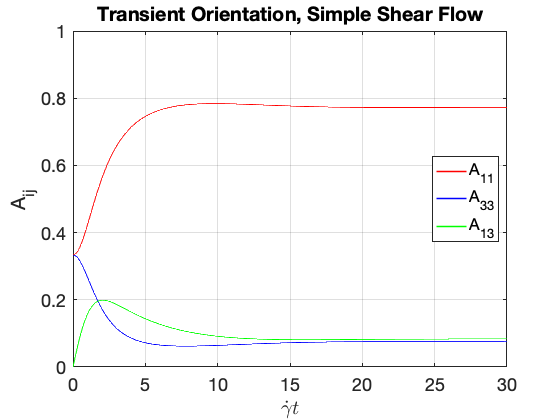

% Plot orientation
figure
plot(t, Av(:,1), 'r-', t, Av(:,3), 'b-', t, Av(:,5), 'g-', ...
     'LineWidth', 1.5)

set(gca, 'FontSize', 18, 'Xtick', 0:5:30)
xlabel('$\dot{\gamma}t$', 'Interpreter', 'LaTeX')
ylabel('A_{ij}')
grid on
box on
legend('A_{11}', 'A_{33}', 'A_{13}', 'Location', 'East')
axis([0 max(t) 0 1])
title('Transient Orientation, Simple Shear Flow')

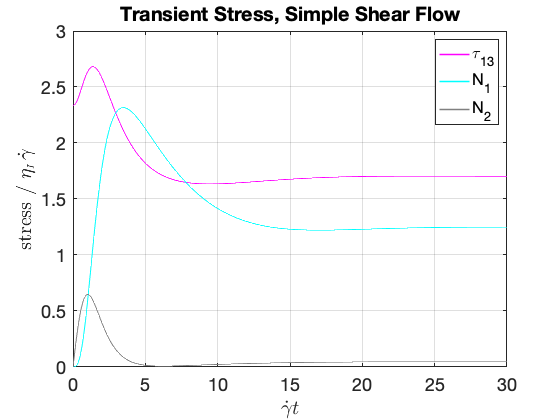


%% Plot stress
figure
hl = plot(t, tauSSF(5,:), 'm-', t, tauSSF(1,:)-tauSSF(3,:), 'c-', ...
          t, tauSSF(3,:)-tauSSF(2,:), 'k-', ...
          'LineWidth', 1.5);

set(gca, 'FontSize', 18, 'Xtick', 0:5:30)
set(hl(3), 'Color', 0.5*[1,1,1])
xlabel('$\dot{\gamma} t$', 'Interpreter', 'LaTeX')
ylabel('stress / $\eta_{\scriptscriptstyle I} \, \dot{\gamma}$', 'Interpreter', 'LaTeX')
grid on
box on
axis([0 max(t) 0 3])
set(gca, 'Xtick', 0:5:30)
legend('\tau_{13}', 'N_1', 'N_2', 'Location', 'NorthEast')
title('Transient Stress, Simple Shear Flow')

This matches Fig. 6.4.  Note that both the shear stress and the normal stresses have an overshoot, and these are related to the overshoot in $A_{13}$.  Also, the shear stress is lower at steady state than it was initially.  When fibers are aligned in the flow direction they do not contribute to the $N_p$ term in the stress, and the steady-state orientation has strong flow-direction orientation.  